# **SISTEMAS DE CONTROL **

# 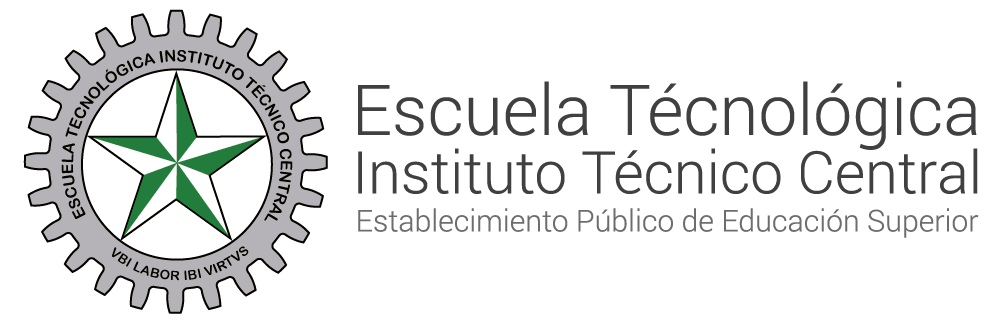

# **Transformada de Fourier**

#### Autor ING. JHEYSON FABIAN VILLAVISAN BUITRAGO 

La Transformada de Fourier toma una señal en el dominio del tiempo y la descompone en sus componentes de frecuencia individuales. En otras palabras, permite representar una señal como una suma (o integral) de sinusoides de diferentes frecuencias, amplitudes y fases. Esta descomposición es útil porque muchas señales en la naturaleza y en la tecnología pueden analizarse de manera más efectiva en términos de sus componentes de frecuencia.


$$f\left(x\right)=\int_{-\infty }^{\infty } F\left\lbrack u\right\rbrack e^{2\pi \mathrm{iux}} \mathrm{dx}$$


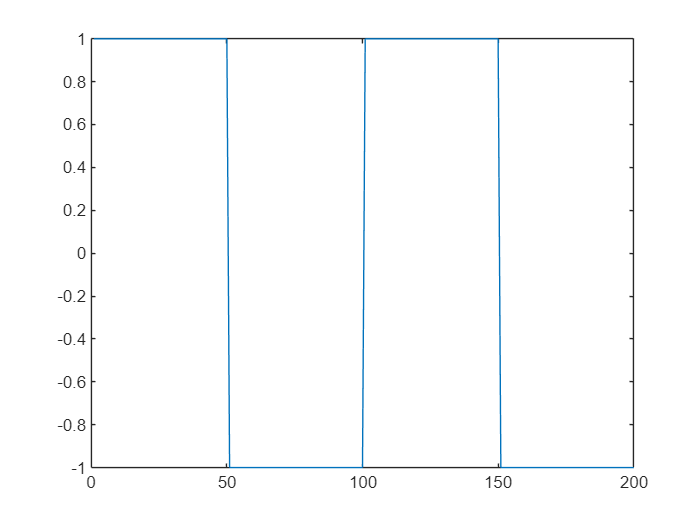

frecuencia = 1;
duracion = 2;
fs = 100;
t = 0:1/fs:duracion-1/fs;
senal_cuadrada = square(2 * pi * frecuencia * t);
plot(senal_cuadrada)

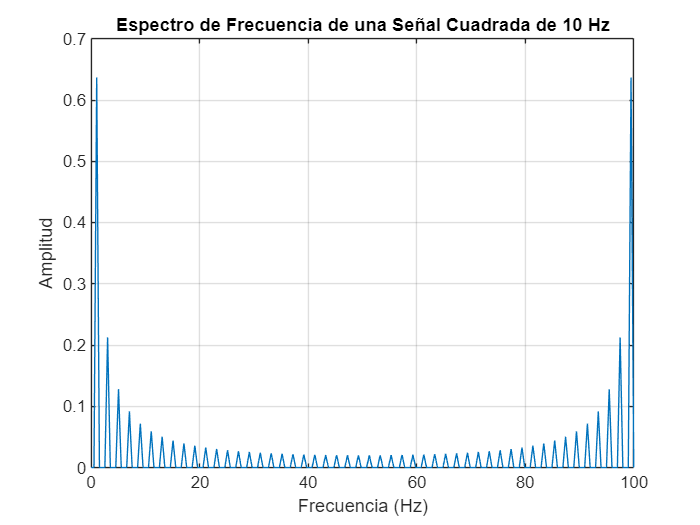

transformada = fft(senal_cuadrada);
frecuencia_hz = linspace(0, fs, length(transformada)); 
espectro = abs(transformada) / length(transformada); 
plot(frecuencia_hz, espectro);
xlabel('Frecuencia (Hz)');
ylabel('Amplitud');
title('Espectro de Frecuencia de una Señal Cuadrada de 10 Hz');
grid on;

## Actividad

- Para cada armónico de la señal producto de la transformada de Fourier grafique señales seno como se observa a continuación:

f(X) = 2*Y sin (X)

donde Y es la amplitud del armónico

X es la frecuencia 

- Para cada señal graficada sume las señales resultantes

- Para cada señal graficada, grafique la transformada de Fourier y sume las señales resultantes.

- Concluya.

El siguiente es el código de ejemplo:

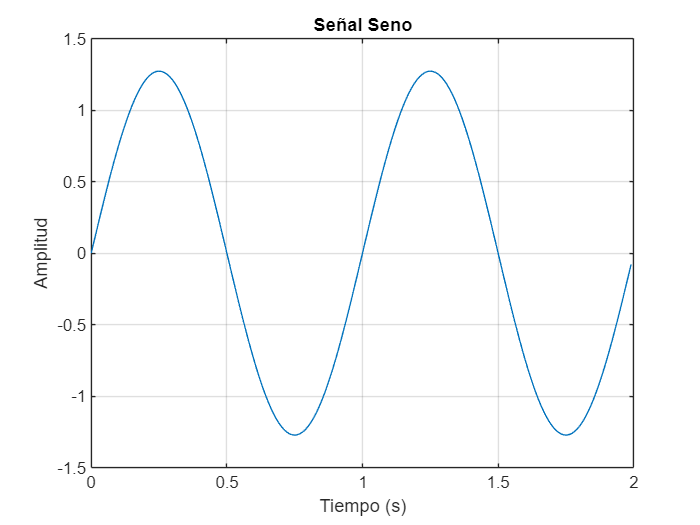

frecuencia = 1;
amplitud = 0.6367;
fase = 0;
duracion = 2;
fs = 100;
t = 0:1/fs:duracion-1/fs;
senal_seno = 2*amplitud * sin(2 * pi * frecuencia * t + fase);
plot(t, senal_seno);
xlabel('Tiempo (s)');
ylabel('Amplitud');
title('Señal Seno');
grid on;

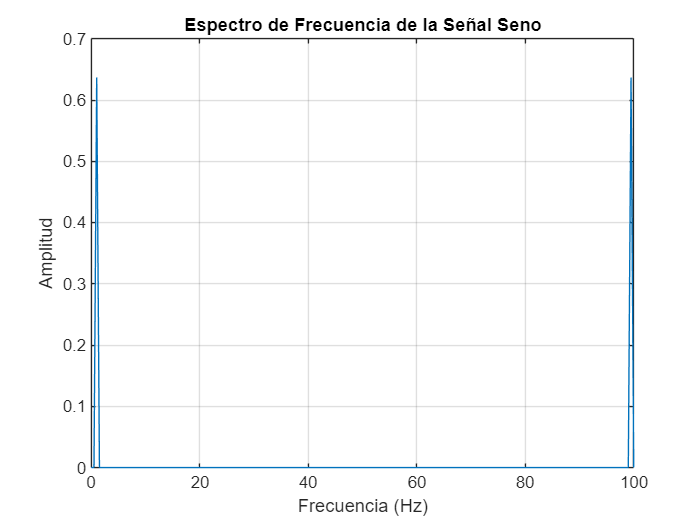

transformada = fft(senal_seno);
frecuencia_hz = linspace(0, fs, length(transformada)); % Eje de frecuencia en Hz
espectro = abs(transformada) / length(transformada); % Normalizar el espectro
figure;
plot(frecuencia_hz, espectro);
xlabel('Frecuencia (Hz)');
ylabel('Amplitud');
title('Espectro de Frecuencia de la Señal Seno');
grid on;